# Q1

help polygon

  Draw a N-polygon
  N     The number of sides
  polygon
  polygon(N)



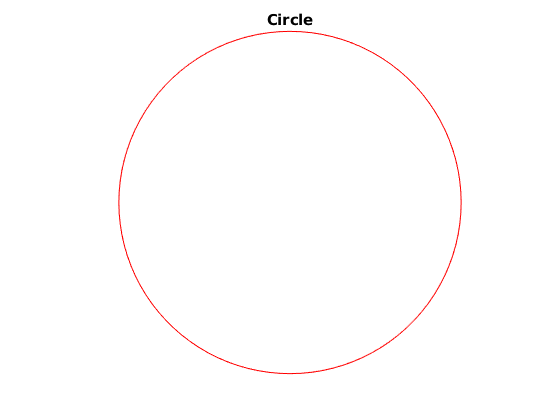

polygon

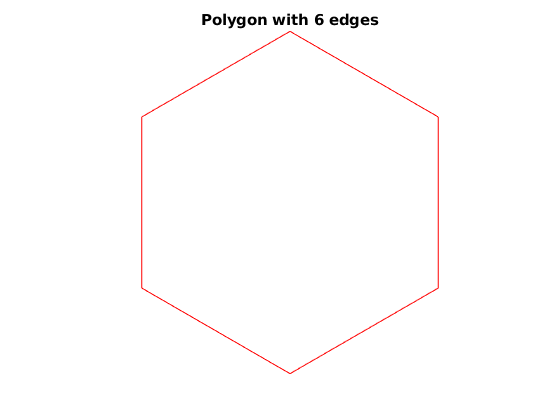

polygon(6)

try
    polygon(0.5)
catch err1
    disp(err1.message)
end

The input should be a natural number.


try
    polygon(2)
catch err2
    disp(err2.message)
end

The input should be greater than 2.


# Q2

syms x
f = @(x)x^2-cos(x)+exp(-x);
x_min1 = fminbnd(f, 0, 1)

x_min1 = 0.2584

f_min1 = f(x_min1)

f_min1 = -0.1277

df = diff(f, x);
d2f = diff(df, x);
x_old = 0;iter = 0;
while(1)
    iter = iter+1;
    x_new = x_old-double(subs(df,x,x_old)/subs(d2f,x,x_old));
    if(abs(x_new-x_old)<1e-8)
        break;
    end
    x_old = x_new;
end
x_min2 = x_new

x_min2 = 0.2584

f_min2 = f(x_min2)

f_min2 = -0.1277

# Q3

syms x
f = @(x)sin(x(1))+exp(x(2))+exp(x(3));
x_min = fmincon(f,[1 0 0],[],[],[],[],[],[],@Q3con)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','1.809092e-08','1.000000e-06','1.332268e-15','1.000000e-06'},true,true);;">stopping criteria details</a

x_min =    -0.6790   -0.5191   -0.5191


# Q4

## (1)

x1 = fminunc(@Q4func, zeros(5,1))


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


x1 =    -0.0001
   -0.0621
    0.7729
   -0.3578
    0.0713


x2 = fminunc(@Q4func, ones(5,1)*(-100))


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


x2 =    -0.0280
   -0.0737
    0.7895
   -0.3995
    0.1344


x3 = fminunc(@Q4func, ones(5,1)*100)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


x3 =    -0.1372
   -0.1560
    0.8730
   -0.5687
    0.3954


可见对于三种初值，fminnunc都计算到了0附近，但是都显示无法继续降低目标函数值。

这是因为1范数在0点不可导。

Q1 polygon.m:

function polygon(N)
% Draw a N-polygon
% N     The number of sides
% polygon
% polygon(N)

% Yangxiao Luo 11/19/2019
if nargin == 0
    N = 100;
end
if fix(N) ~= N
    error('The input should be a natural number.')
elseif N<3
    error('The input should be greater than 2.')
end
t=0:2*pi/N:2*pi;
x=sin(t);
y=cos(t);
plot(x,y,'r');
axis equal
axis off
if nargin == 0
    title('Circle')
else
    title(['Polygon with ' int2str(N) ' edges'])
end
end

Q3 contraint function:

function [c,ceq] = Q3con(x)
ceq = x(1)^2+x(2)^2+x(3)^2-1;
c = [];
end

Q4 objective function:

function y = Q4func(x)
rng default
A = rand(5);
B = rand(5);
b = rand(5,1);
lambda = 0.1;
y = (norm(A*x-b,2)^2)/2+lambda*norm(B*x,1);
end